Pneumonia Detection via X-ray Image Processing


clc; clear; close all;

%%Create Data Stores
d1 = "stage_2_train_images/Positive/";
Pfiles = dir(fullfile(d1));
Pfiles([Pfiles.isdir]) = [];
n_Pfiles = length(Pfiles);

d2 = "stage_2_train_images/Negative/";
Nfiles = dir(fullfile(d2));
Nfiles([Nfiles.isdir]) = [];
n_Nfiles = length(Nfiles);

%Labels array
pos_label = strings(n_Pfiles,1);
pos_label(1:end) = "positive";
neg_label = strings(n_Nfiles,1);
neg_label(1:end) = "negative";
labels = [pos_label;neg_label];

%%Initiate variable arrays
LungSize = zeros(size(labels));
AveValues = zeros(size(labels));

Running Positive training images through Image Processing


for i = 1:n_Pfiles
     filename = fullfile(d1, Pfiles(i).name);
%     Read file and gray scale
    img = dicomread(filename);
    img = im2gray(img);
    img = imadjust(img);
%     Invert image 
    testimg = 255 - img;
    testimg_clear = imclearborder(testimg);
    testimg_clear_inv = 255-testimg_clear;
%     Find lungs
    I = testimg_clear_inv;
    [BW, thresh] = edge(I,'sobel');
    fudgeFactor = 0.8;
    Iedge = edge(I,'sobel',fudgeFactor*thresh);
%     Dilate, fill holes, and erode
    se90 = strel('line',6,90);
    se0 = strel('line',3,0);
    Idilate = imdilate(Iedge,[se90, se0]);
    Ifill = imfill(Idilate, 'holes');
    seD = strel('diamond', 3);
    Ierode1 = imerode(Ifill,seD);
    Ierode2 = imerode(Ierode1,seD);
    Ierode3 = imerode(Ierode2,seD);
    Ifinal = imerode(Ierode3,seD);
%     Find variables
    Ave_val = mean(img(Ifinal));
    num_pixels = sum(Ifinal(:));
%     Variable vectors
    LungSize(i) = num_pixels;
    AveValues(i) = Ave_val;
end

Running Negative training images through Image Processing


for j = 1:n_Nfiles
     filename = fullfile(d2, Nfiles(j).name);
%     Read file and gray scale
    img = dicomread(filename);
    img = im2gray(img);
    img = imadjust(img);
%     Invert image 
    testimg = 255 - img;
    testimg_clear = imclearborder(testimg);
    testimg_clear_inv = 255-testimg_clear;
%     Find lungs
    I = testimg_clear_inv;
    [BW, thresh] = edge(I,'sobel');
    fudgeFactor = 0.8;
    Iedge = edge(I,'sobel',fudgeFactor*thresh);
%     Dilate, fill holes, and erode
    se90 = strel('line',6,90);
    se0 = strel('line',3,0);
    Idilate = imdilate(Iedge,[se90, se0]);
    Ifill = imfill(Idilate, 'holes');
    seD = strel('diamond', 3);
    Ierode1 = imerode(Ifill,seD);
    Ierode2 = imerode(Ierode1,seD);
    Ierode3 = imerode(Ierode2,seD);
    Ifinal = imerode(Ierode3,seD);
%     Find variables
    Ave_val = mean(img(Ifinal));
    num_pixels = sum(Ifinal(:));
%     Variable vectors
    LungSize(n_Pfiles+j) = num_pixels;
    AveValues(n_Pfiles+j) = Ave_val;
end
        

Create Output table to be used in Learning Models

%creating the table output
    Model_Table = table(labels,LungSize,AveValues)

Model_Table = 55×3 table
      labels       LungSize     AveValues
    __________    __________    _________

    "positive"         33368     98.302  
    "positive"         96527     156.41  
    "positive"         13854      72.44  
    "positive"         23459     105.34  
    "positive"    1.1748e+05     108.11  
    "positive"    1.6133e+05     71.452  
    "positive"    1.1295e+05         82  
    "positive"           696     77.185  
    "positive"          8517     66.213  
    "positive"          5009      87.36  
    "positive"         94079     123.86  
    "positive"         56328     148.21  
    "positive"     1.183e+05     104.69  
    "positive"     1.408e+05     65.005  
    "positive"          1372      48.17  
    "positive"         94580     70.651  


Run Models

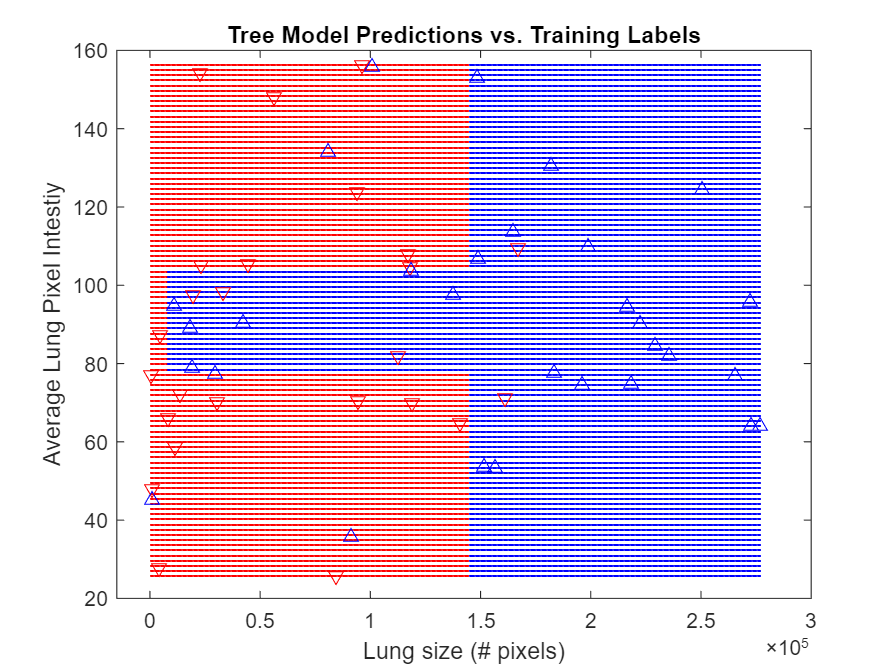

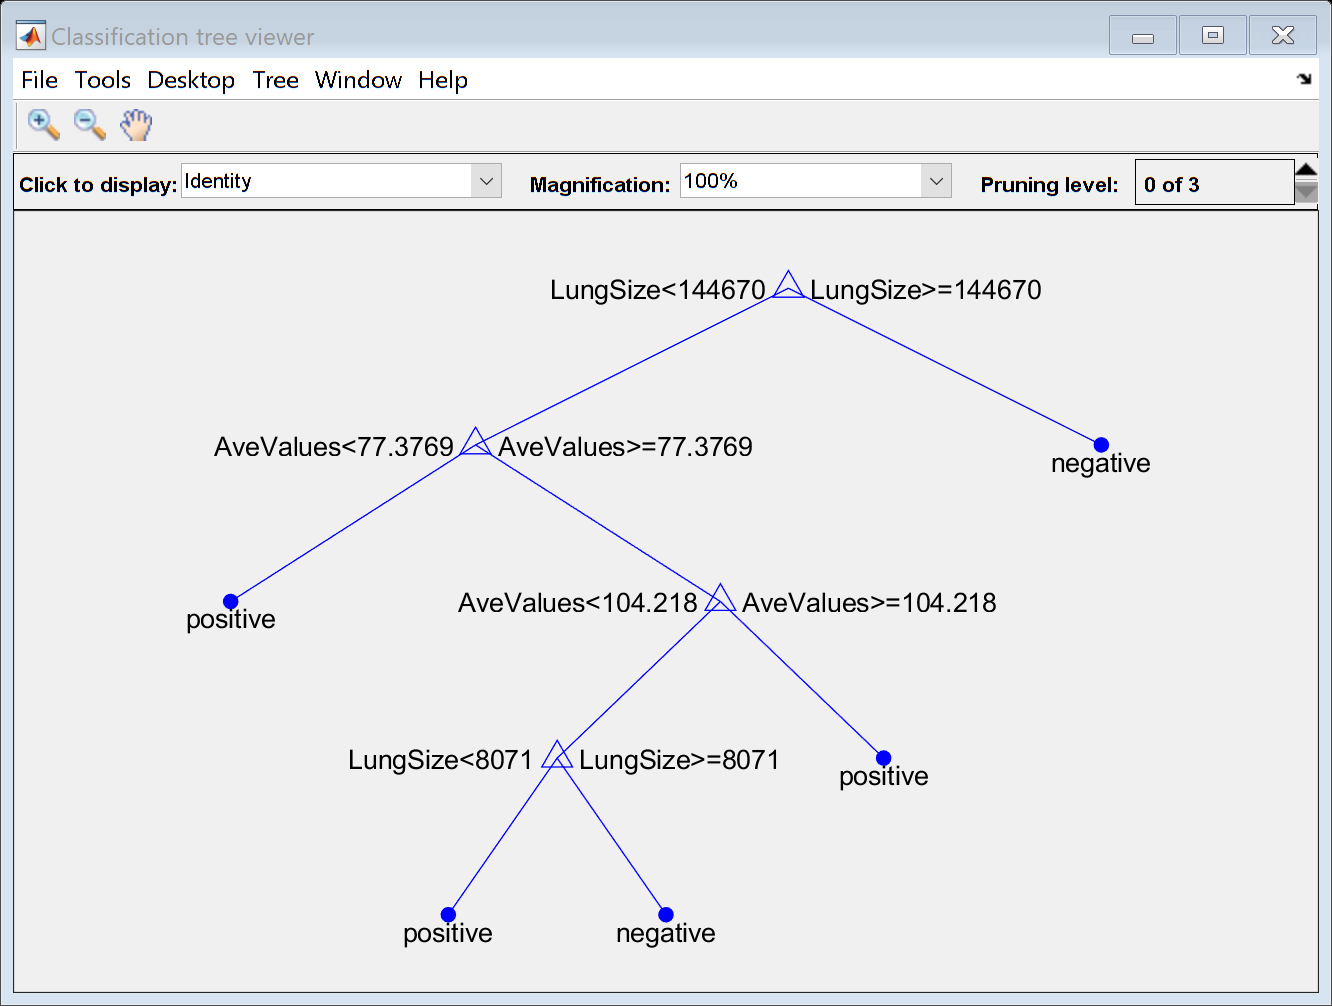

addpath('Model_Functions\')
figure(1)
Tree = d_tree(Model_Table);

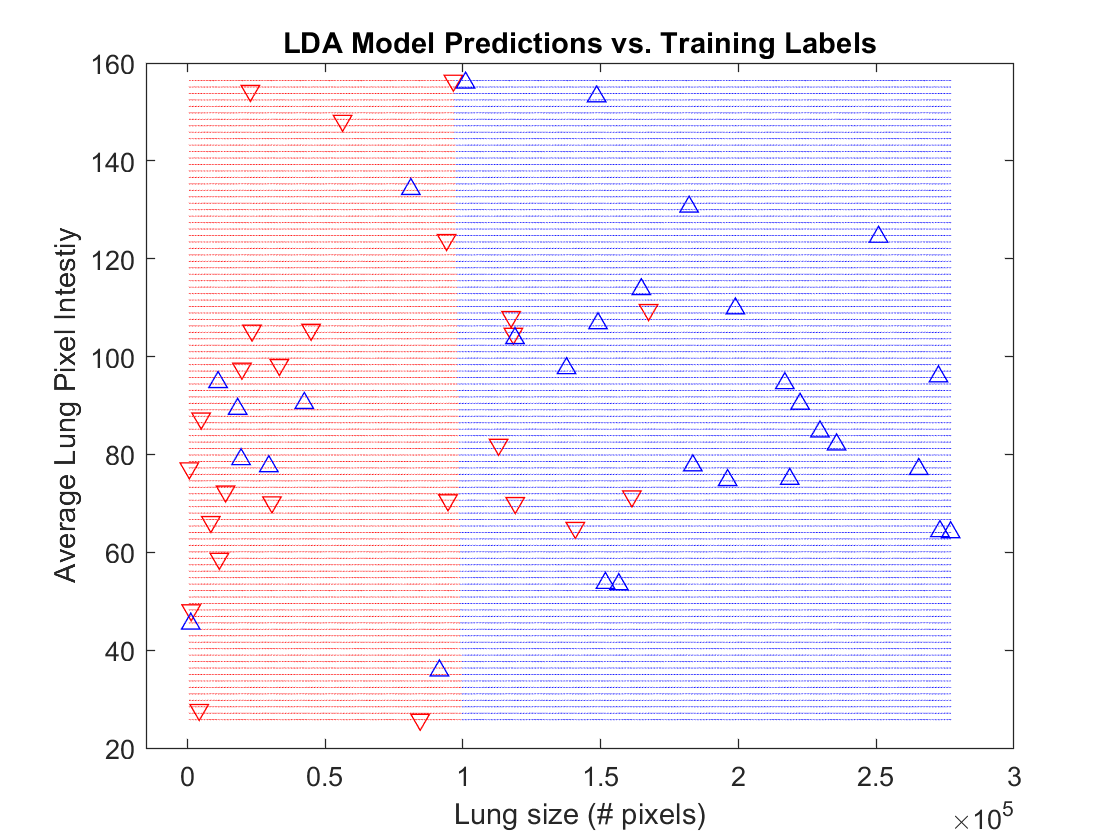

figure(2)
LDA = LDA(Model_Table);

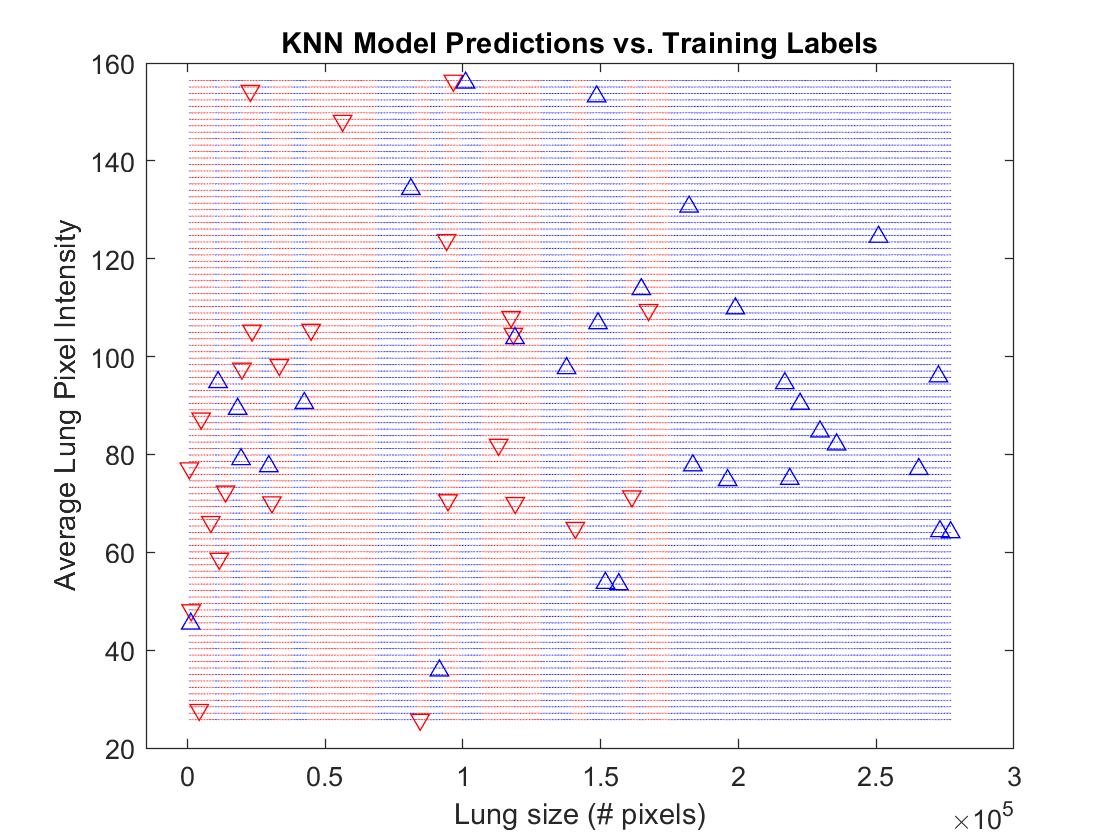

figure(3)
KNN = KNN(Model_Table);


save([pwd '/Trained_Models/KNN.mat'] , 'KNN')
save([pwd '/Trained_Models/LDA.mat'], 'LDA')
save([pwd '/Trained_Models/Tree.mat'], 'Tree')